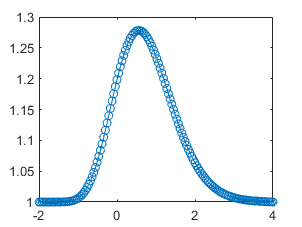

clear; clc;
N = 141; nu=1;
x = linspace(-2,4,N+1); 
dx= 0.043;
dt=0.0055; 
tf=50*dt;
M=tf/dt;
%++++++++++++++++++++++++++++++++++++++++++++++++
u = ones(N+1,1);
for i=1:N+1
	if x(i)>0.5 && x(i)<1
		u(i)=2;
    end
end
%++++++++++++++++++++++++++++++++++++++++++++++++
for n=1:M
	un=u;
    for i=2:N
		u(i)=(un(i)+(nu*dt/dx^2)*(u(i-1)-un(i)+un(i+1)))/(1+nu*dt/dx^2);
        %u(i)=un(i)+(nu*dt/dx^2)*(un(i+1)-2*un(i)+-un(i-1)) ;
    end
    u(N+1)=1;
    u(1)=1;
    plot(x,u,'-o')
    pause(0.2)
end